# Clear environment

clc;
clear teta f k mat ros;
close;

## Calculating Charge Density

## Initializing variables

ro0 = 1; ro1 = -1; n = 512;
h = 2*pi/n; a = 1; d = 10;

## Initializing pre-computations

I = 4*(log(2)*sin(h/2)+2*(sin(h/2)*log(sin(h/2))-sin(h/2)));
B = a*log(a)-a/2*log(2*a^2);
A = 2*h*B;

## Calculating intermidiate variables

for i = 0:n-1
    teta(i+1) = i*h;
    f(i+1) = ro0*(log(d) - 0.5*log(a^2+d^2-2*a*d*cos(teta(i+1))));
    if i > 0
        k(i+1) = B-a/2*(log(2*sin(teta(i+1)/2)));
    end
    if i==0
        k(i+1)=A-a/2*I;
    else
        if i == 1
            k(i+1) = h/3*k(i+1);
        else
            if i == n - 1
                k(i+1) = h/3*k(i+1);
            else
                k(i+1) = 2*h/3*(1+mod(i+1,2)*k(i+1));
            end
        end
    end
end
for i=0:n-1
    for j=0:n-1
        mat(i+1,j+1)=k(1+mod(j-i+n,n));
    end
end
f=-f;f=f';ros=mat\f;su=0;
for i=1:n
    su=su+ros(i);
end
for i=1:n
    ros(i)=-su/n + ros(i) + ro1/(2*pi*a);
    x(i)=pi/180*(i-n/2-1);
end
ros(n+1)=ros(1);
x(n+1)=pi/180*(i-n/2);

## Plotting section

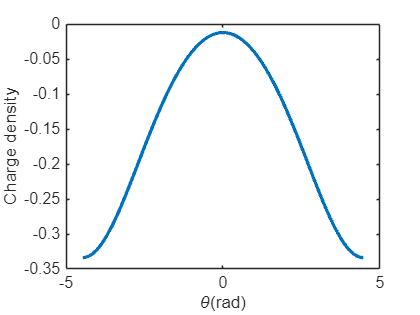

plot(x,ros,'LineWidth',2);
ylabel('Charge density');
xlabel('\theta(rad)');